sympref('MatrixWithSquareBrackets', true);

# Ebola outbreak II

## 1 Process I

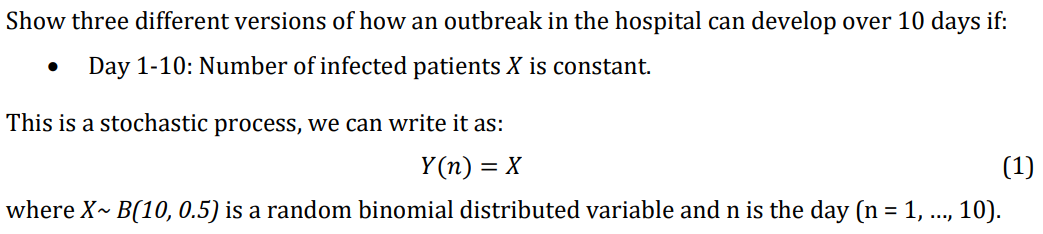

### 1.1 Make a Matlab function that generates realizations of the process Y(n).

Pr_Infected = 0.5;
patients = 10;
days = 10;
sz_1 = 1;
sz_2 = 3;

y_1_n = binornd(patients, Pr_Infected, sz_1, sz_2);
display(y_1_n);

y_1_n =      4     2     7


### 1.2 Plot three realizationer of the process. 

figure(1)
for n=1:3
 ax=subplot(sz_2,sz_1,n); %Plot of three realizations
 x=linspace(0,10,11);
 plot(ax,x,y_1_n(n),'kx')
 axis([0,10,0,10])
 title(ax,['Realization ',num2str(n)])
 xlabel(ax,'Day')
 ylabel(ax,'Infected')
end

### 1.3  What is the ensemble mean and variance of the process? 

ens_mean = patients * Pr_Infected;
display(ens_mean)

ens_mean = 5

ens_var = patients * Pr_Infected * (1 - Pr_Infected);
display(ens_var)

ens_var = 2.5000

### 1.4 What is the mean and variance of the process of one realisation? 

real_mean_1 = mean(y_1_n(1));
display(real_mean_1);

real_mean_1 = 4

real_var_1 = var(y_1_n(1));
display(real_var_1);

real_var_1 = 0

### 1.5 Verify Question 3 and 4 with the Matlab function.

y_n_1_sim = binornd(patients, Pr_Infected, 1, 10000);
ens_mean = mean(y_n_1_sim);
display(ens_mean)

ens_mean = 5.0074

ens_var = var(y_n_1_sim);
display(ens_var);

ens_var = 2.4666

### 1.6 Is the process 𝑌(𝑛) Wide Sense Stationary (WSS), and is it ergodic? 

## 2 Process II

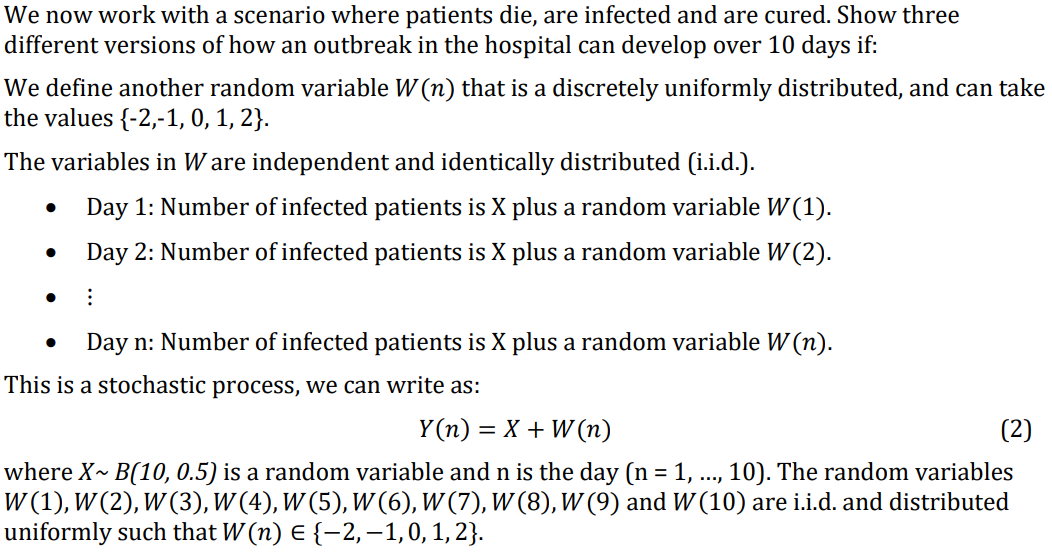

### 2.1 Make a Matlab function that generates realizations of the process 𝑌(𝑛).

### 2.2 Plot three realizationer of the process. 

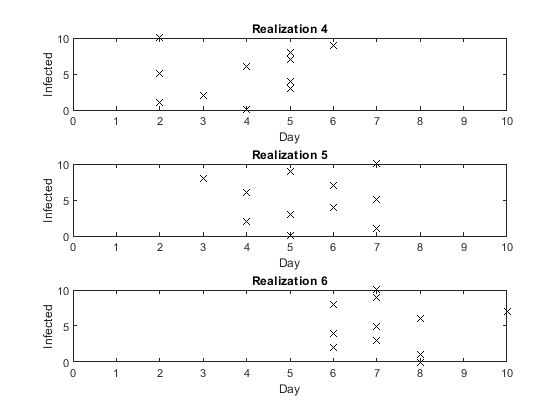

lower = -2;
upper = 2;

figure(2)
for n=4:6
    x = binornd(patients, Pr_Infected, 1);
    wn = randi([lower, upper], 1, days + 1);
    wn(1) = 0;
    y_n = wn + x;
    ax = subplot(3,1,n-3);
    line_space = linspace(0,10,11);
    plot(ax, y_n, line_space, 'kx')
    axis([0,10,0,10])
    title(ax,['Realization ',num2str(n)])
    xlabel(ax,'Day')
    ylabel(ax,'Infected')
end

### 2.3  What is the ensemble mean and variance of the process?

ens_mean = (upper + lower) / 2 + patients * Pr_Infected;
display(ens_mean);

ens_mean = 5

ens_var =((upper-lower+1)^2-1)/12+patients*Pr_Infected*(1-Pr_Infected);
display(ens_var);

ens_var = 4.5000

### 2.4 What is the mean and variance of the process of one realisation? 

real_mean = mean(y_n);
display(real_mean);

real_mean = 7.2727

real_var = var(y_n);
display(real_var);

real_var = 1.4182

### 2.5 Verify Question 3 and 4 with the Matlab function.

y_n_sim = binornd(patients, Pr_Infected, 1, 10000) + randi([lower upper], 1, 10000);

ens_mean_sim = mean(y_n_sim);
display(ens_mean_sim);

ens_mean_sim = 4.9959

ens_var_sim = var(y_n_sim);
display(ens_var_sim);

ens_var_sim = 4.4757

### 2.6 Is the process 𝑌(𝑛) Wide Sense Stationary (WSS), and is it ergodic? 

Den er *Wide Sense Stationary* da middelværdien i gennemsnit altid vil være konstant for ensemble. 

Den er Ikke *Ergodiski *da middelværdien for ensemble er forskelligt til tidspunktet.

## 3 Process III

### 3.1 Day 1-10:

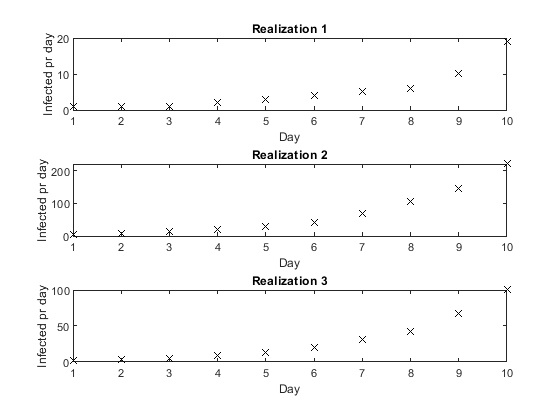

Number_infected_day =      1     1     1     2     3     4     5     6    10    19


Number_infected_day =      5     8    14    21    29    42    69   104   146   220


Number_infected_day =      2     4     5     9    13    20    31    43    67   100


population = rand(1, 1000);
infected = 1:length(population);
symptoms = 1:length(population);

for n=1:length(population)
    if population(n) < 0.2
        infected(n) = 1;
        symptoms(n) = 1;
    elseif 0.2 < population(n) && population(n) <= 0.5
        infected(n) = 0;
        symptoms(n) = 1;
    elseif population(n) > 0.99
        infected(n) = 1;
        symptoms(n) = 0;
    else
        infected(n) = 0;
        symptoms(n) = 0;
    end
end

N_tot_realizations = 3;
figure(1)
for N_realization=1:N_tot_realizations
    N = randi(length(population), 1, 10);
    N_Infected(1:days) = 0;
 for k=1:10
    N_Infected(1) = N_Infected(1) + infected(N(k));
 end

 for day=2:days
    N_Infected(day) = N_Infected(day-1);
     for n=1:N_Infected(day-1)
        Infected_new = randi(2) - 1;
        N_Infected(day) = N_Infected(day) + Infected_new;
     end
end
Number_infected_day = N_Infected;
display(Number_infected_day);

ax = subplot(3, 1, N_realization);
plot(ax, 1:10, N_Infected, 'kx');
title(ax,['Realization ',num2str(N_realization)]);
xlabel(ax,'Day');
ylabel(ax,'Infected pr day');


end

### 3.5 Is this process Wide Sense Stationary (WSS), and is it ergodic?

    Den er ikke *Wide Sense Stationary* da middelværdien stiger med tiden.

    Den er ikke ergodisk da den ikke er *Wide Sense Stationary*.